This live script will test different filters on a Gaussian

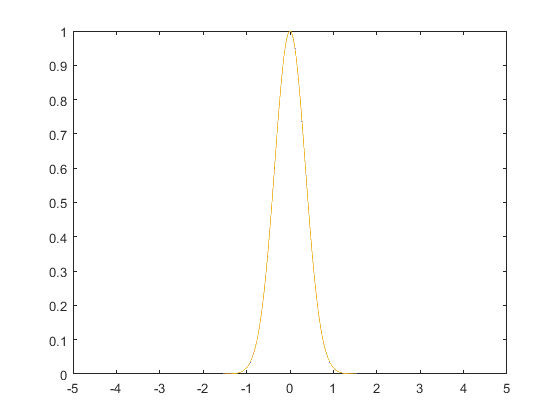

x = linspace(-3, 3, 6000);
y = exp(-x.^2/.5^2);
plot(x, y);


addpath(strcat(pwd, '/../../ETPAlgorithm/dependencies/fieldtrip-20201214'));
ft_defaults; % initializes field trip

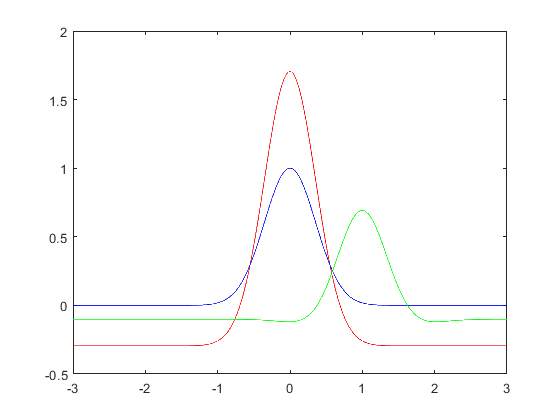

fs = 1000; % 1000 samples per second
% filtered = ft_preproc_bandpassfilter(y, fs, [0 10], [], 'fir', 'twopass');
filtered = ft_preproc_highpassfilter(y, fs, 0.15, [], 'brickwall', 'onepass');
filtered2 = ft_preproc_highpassfilter(y, fs, 0.15, [], 'fir', 'onepass');
clf;
plot(x, filtered, 'red');
hold on;
plot(x, y, 'blue');
hold on;
plot(x, filtered2, 'green');